# Atividade 05 - Operações no domínio de Fourier e suas implicações temporais

## Boas prátiacas

clear;                  %%% limpando todas as variáveis
close all;              %%% fechando todas as figuras
clc;                    %%% limpando a tela

## Valor eficaz de um sinal

## Exercício 1

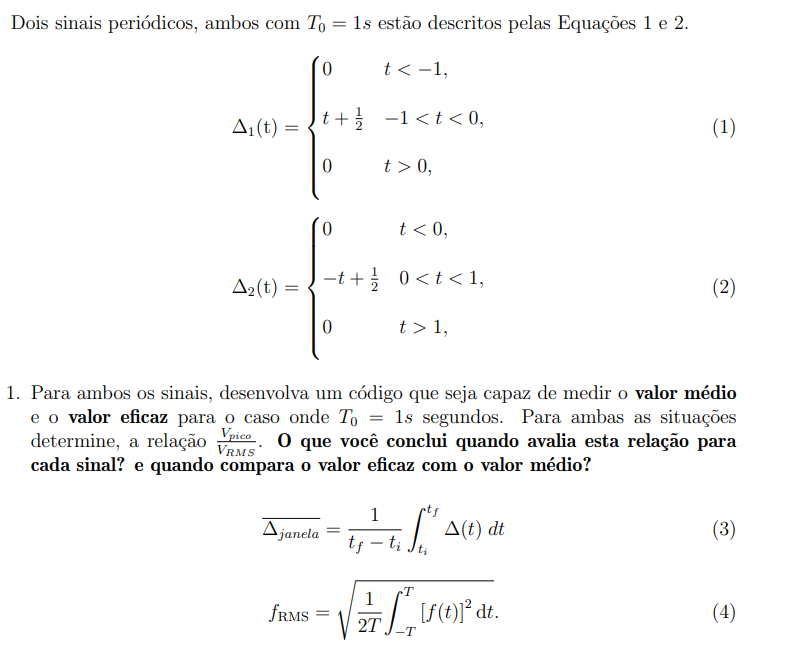

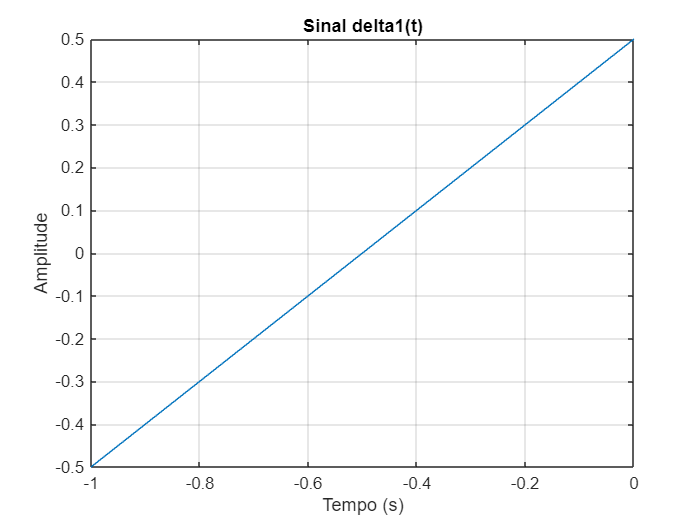

%%% Exibição dos sinais originais 
tempoDelta1 = -1:1e-3:0;
delta1 = tempoDelta1+0.5;
plot(tempoDelta1, delta1);
title('Sinal delta1(t)'), xlabel('Tempo (s)'), ylabel('Amplitude'), grid;

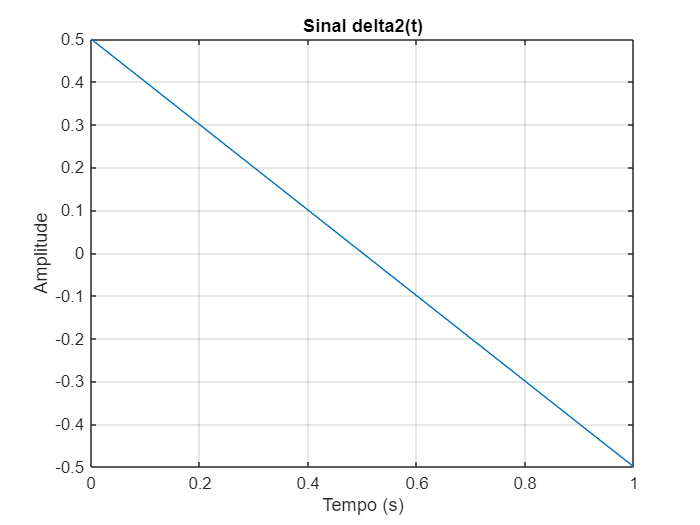

%%%I = 1i;
tempoDelta2 = 0:1e-3:1;
delta2 = -tempoDelta2+0.5;
plot(tempoDelta2, delta2);
title('Sinal delta2(t)'), xlabel('Tempo (s)'), ylabel('Amplitude'), grid;

%%% Determinação dos valores médios 
syms t n;
T0 = 1;
V_medio1 = 1/T0 * int(t + 0.5, t, -1, 0)

$$V\_medio1 = 0$$

V_medio2 = 1/T0 * int(-t + 0.5, t, 0, 1)

$$V\_medio2 = 0$$

%%% Determinação dos valores eficazes (RMS)
Vpico1 = 0.5;
Vrms1 = sqrt(1/T0 * int((t + 0.5)^2, t, -1, 0))

$$Vrms1 = \frac{\sqrt{3}}{6}$$

Vpico2 = 0.5;
Vrms2 = sqrt(1/T0 * int((-t + 0.5)^2, t, 0, 1))

$$Vrms2 = \frac{\sqrt{3}}{6}$$

%%% Valor da primeira razão Vpico1/Vrms1
Razao1 = Vpico1 / Vrms1

$$Razao1 = \sqrt{3}$$

%%% Valor da segunda razão Vpico2/Vrms2
Razao2 = Vpico2 / Vrms2

$$Razao2 = \sqrt{3}$$

## Exercício 2

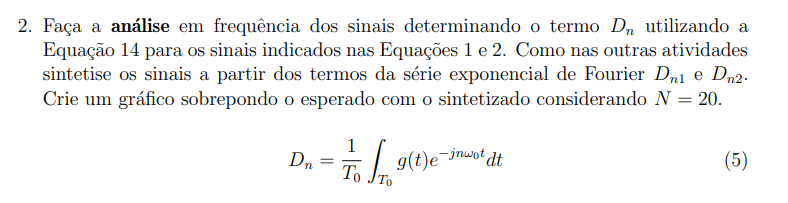

%%% Determinando os coeficientes Dn
w01 = 2*pi/T0;
Dn1 = (1/T0) * int((t+0.5)*exp(-1j*n*w01*t), t, -1, 0)

$$Dn1 = \frac{\frac{1}{4}+\pi \,n\,\left(\frac{{\mathrm{e}}^{2\,\pi \,n\,\mathrm{i}}\,\mathrm{i}}{4}+\frac{1}{4}\,\mathrm{i}\right)-\frac{{\mathrm{e}}^{2\,\pi \,n\,\mathrm{i}}}{4}}{n^{2}\,\pi^{2}}$$

w02 = 2*pi/T0;
Dn2 = (1/T0) * int((-t+0.5)*exp(-1j*n*w02*t), t, 0, 1)

$$Dn2 = \frac{1}{4\,n^{2}\,\pi^{2}}+\frac{\left({\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1\right)\,\mathrm{i}}{4\,n\,\pi }-\frac{{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}\,\left(1+2\,\pi \,n\,\mathrm{i}\right)}{4\,n^{2}\,\pi^{2}}$$

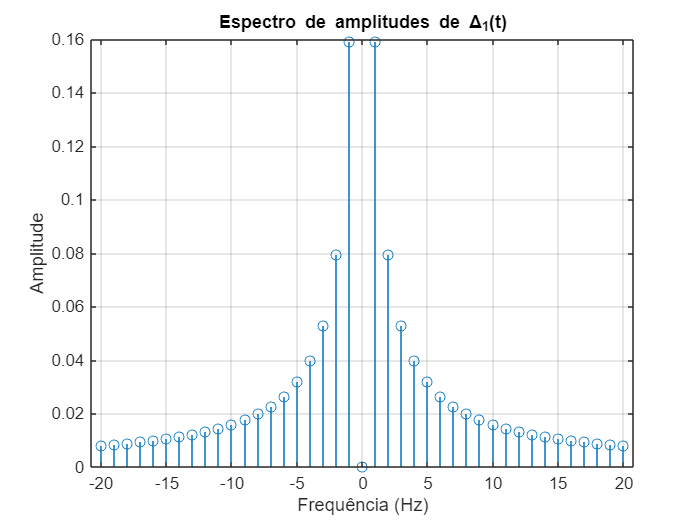

%%% Espectro de frequência para delta1
N=20;
n = -N:1:N;
amplitudes1 = abs(eval(Dn1));
amplitudes1(N+1) = V_medio1;
freq1 = linspace(-N, N, 2*N+1);

%%% Plotando o espectro de amplitudes 
figure;
stem(freq1, amplitudes1), grid;
title('Espectro de amplitudes de \Delta_1(t)')
xlabel('Frequência (Hz)'), ylabel('Amplitude');

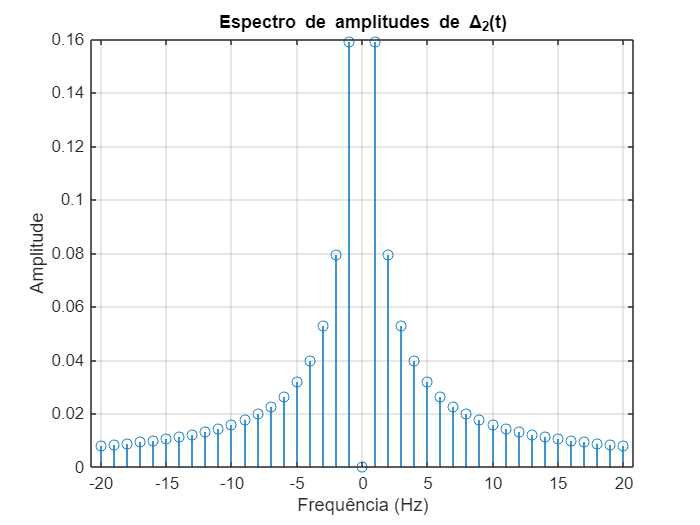

%%% Espectro de frequência para delta2
amplitudes2 = abs(eval(Dn2));
amplitudes2(N+1) = V_medio2;
freq2 = linspace(-N, N, 2*N+1);

%%% Plotando o espectro de amplitudes 
figure;
stem(freq2, amplitudes2), grid;
title('Espectro de amplitudes de \Delta_2(t)')
xlabel('Frequência (Hz)'), ylabel('Amplitude');

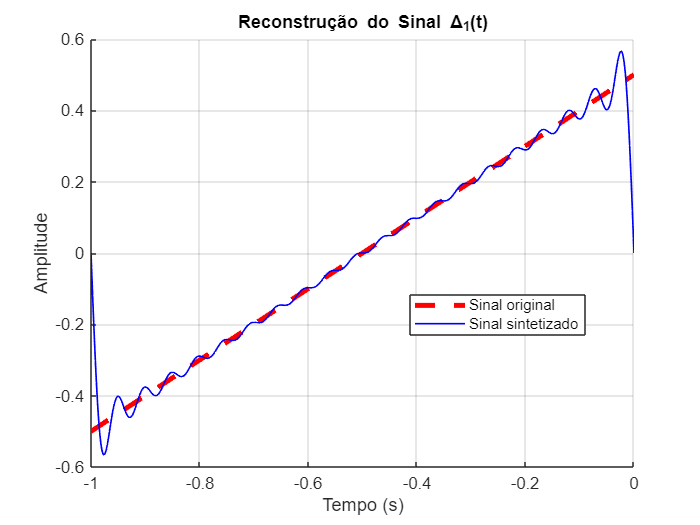

% Síntese dos sinais delta1
Dn1_1 = eval(Dn1);
Dn1_1(N+1) = V_medio1;
aux=0;

for k=1:length(n)
    aux = aux + Dn1_1(k) * exp(1j * n(k) * w01 .* tempoDelta1);
end 

figure;
hold on;
plot(tempoDelta1,delta1,"Color",'r','LineWidth',3,'LineStyle','--');
plot(tempoDelta1,real(aux),'LineWidth',1,"Color",'b');
hold off
title('Reconstrução do Sinal \Delta_1(t)'),xlabel('Tempo (s)'),ylabel('Amplitude'), grid;
legend('Sinal original', 'Sinal sintetizado', 'Location','best')

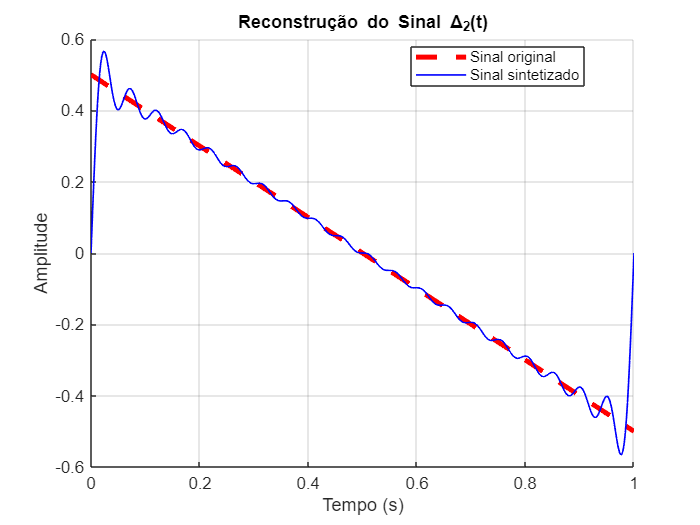

%%% Síntese dos sinais delta2
Dn2_2 = eval(Dn2);
Dn2_2(N+1) = V_medio2;
aux2=0;

for a=1:length(n)
    aux2 = aux2 + Dn2_2(a) * exp(1j * n(a) * w02 .* tempoDelta2);
end 

figure;
hold on;
plot(tempoDelta2,delta2,"Color",'r','LineWidth',3,'LineStyle','--');

plot(tempoDelta2,real(aux2),'LineWidth',1,"Color",'b');
hold off
title('Reconstrução do Sinal \Delta_2(t)'),xlabel('Tempo (s)'),ylabel('Amplitude'), grid;
legend('Sinal original', 'Sinal sintetizado', 'Location','best')

## Exercício 3

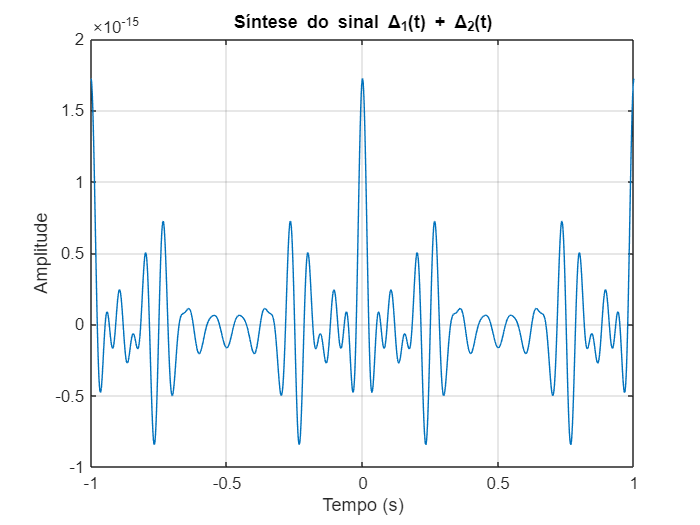

Dn = Dn1_1 + Dn2_2;
aux3 = 0;
tempo = -1:1e-3:1;
for b=1: length(n)
    aux3 = aux3 + Dn(b) * exp(1j * n(b) * w01 .*tempo);
end 

plot(tempo, real(aux3))
xlabel('Tempo (s)'), ylabel('Amplitude'), grid;
title('Síntese do sinal \Delta_1(t) + \Delta_2(t)')

Teoricamente, o sinal sintezidado deveria ser zero. Porém, graficamente, estamos considerando valores na ordem de ${10}^{-15}$por conta da imprecisão do software (que aborta métodos numéricos para resolução). Podemos aproximá-los a zero, sem problema algum.  

## Correlação entre sinais

## Exercício 1

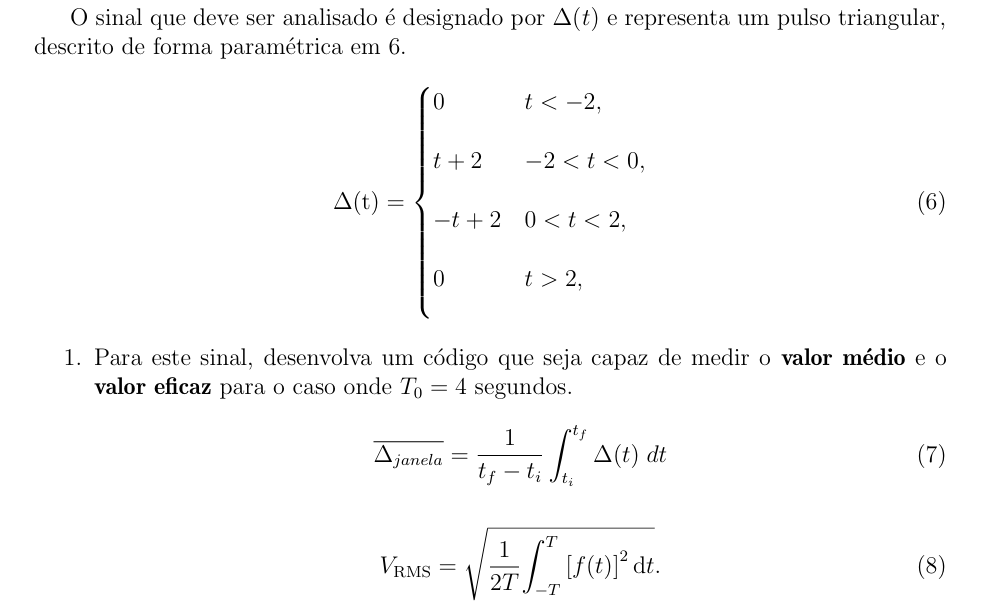

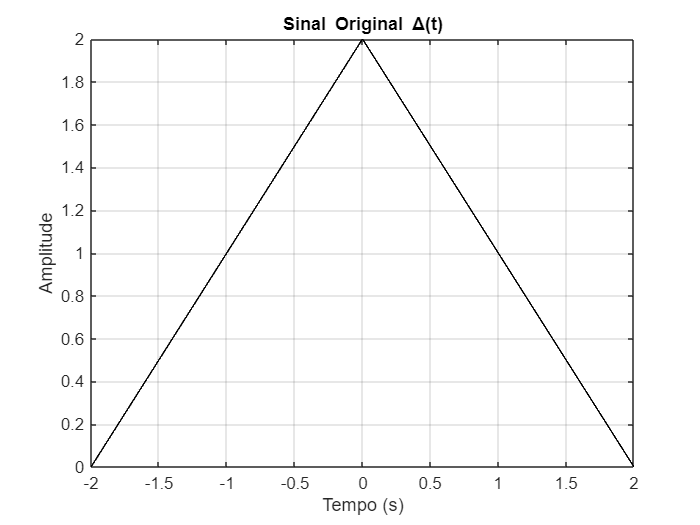

%%% Exibição do pulso triangular analisado

%%% Criando um ambiente simbólico
syms t 
T03 = 4;                   %%% Período fundamental do sinal (10 segundos)
tempo = -2:1e-3:2;         %%% tempo total
w03 = (2*pi)/T03;          %%% frequência angular 

%%% Inicialização do pulso triangular
delta = 2*tripuls(tempo, T03);

%%% Plotando deltaT0
plot(tempo, delta,'LineWidth',1,'Color','k');
title('Sinal Original \Delta(t)');
xlabel('Tempo (s)'),ylabel('Amplitude'),grid;

%%% Valor médio
V_medio3 = 1/T03 * (int(t+2, t, -2, 0) + int(-t+2, t, 0, 2))

$$V\_medio3 = 1$$

%%% valor RMS
Vrms3 = sqrt(1/T03 * int((t+2)^2, t, -2, 0) + 1/T03 * int((-t+2)^2, t, 0, 2))

$$Vrms3 = \frac{2\,\sqrt{3}}{3}$$

## Exercício 2

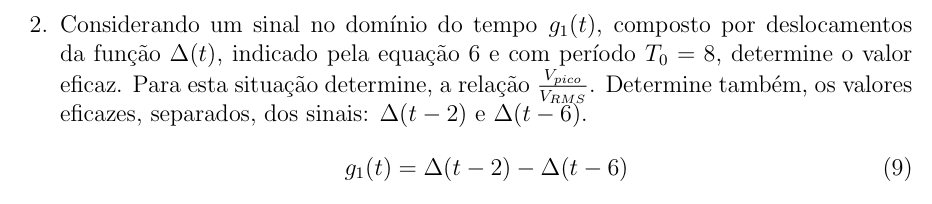

%%% Determinando os coeficientes Dn para o sinal Delta(t)
T04 = 8;
w04 = 2*pi/T04;   

%%% Valor eficaz para g1(t) = Delta(t-2) - Delta(t-6)
Vrms4 = sqrt(1/T04 * (int(t^2, t,0,2) + int((-t+4)^2, t, 2, 6) + int((t-8)^2, t, 6, 8)))

$$Vrms4 = \frac{2\,\sqrt{3}}{3}$$

%%% Determinação da razão Vpico/Vrms
Vpico4 = 2;     % obtido graficamente (atividade anterior)
Razao4 = Vpico4/Vrms4

$$Razao4 = \sqrt{3}$$

%%% Valores eficazes para os sinais separados delta(t-2) e delta(t-6)
Vrms5 = sqrt(1/T04 * (int(t^2, t, 0, 2) + int((-t+4)^2, t, 2, 4)))  % Vrms para Delta(t-2)

$$Vrms5 = \frac{\sqrt{2}\,\sqrt{3}}{3}$$

Vrms6 = sqrt(1/T04 * (int((-t+4)^2, t, 4, 6) + int((t-8)^2, t, 6, 8)))  % Vrms para Delta(t-6)

$$Vrms6 = \frac{\sqrt{2}\,\sqrt{3}}{3}$$

## Exercício 3

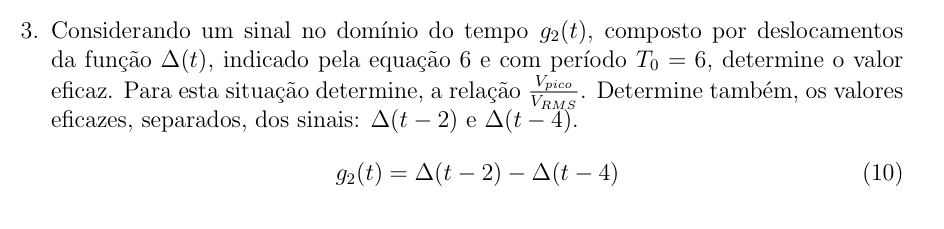

T05 = 6;
w05 = 2*pi/T05;

%%% Valor eficaz para g2(t) = Delta(t-2) - Delta(t-4) e razão Vpico/Vrms
Vrms7 = sqrt(1/T05 * (int(t^2, t,0,2) + int((-t+4)^2, t, 2, 4) + int((-t+2)^2, t, 2, 4) + int((t-6)^2, t, 4, 6)))

$$Vrms7 = \frac{4}{3}$$

Razao5 = 2/Vrms7            % Valor de pico vale 2

$$Razao5 = \frac{3}{2}$$

Vrms8 = sqrt(1/T05 * (int(t^2, t, 0, 2) + int((-t+4)^2, t, 2, 4)))  % Vrms para Delta(t-2)

$$Vrms8 = \frac{2\,\sqrt{2}}{3}$$

Vrms9 = sqrt(1/T05 * (int((-t+2)^2, t, 2, 4) + int((t-6)^2, t, 4, 6)))  % Vrms para Delta(t-6)

$$Vrms9 = \frac{2\,\sqrt{2}}{3}$$

## Exercício 4 

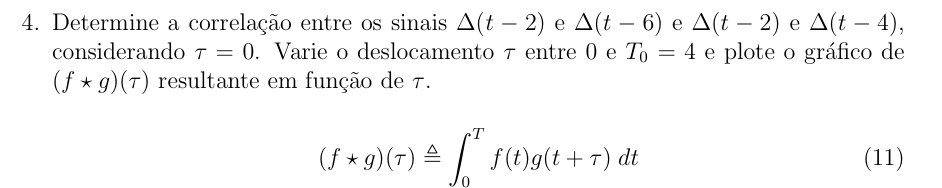

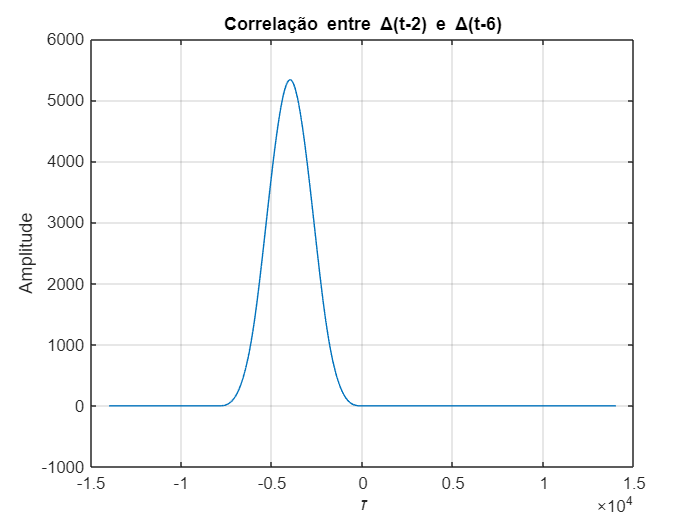

%%% Correlação cruzada entre delta(t-2) e delta(t-6)
T0=4;
tempo = -4:1e-3:10;
[r, largs] = xcorr(2*tripuls(tempo-2,T0), 2*tripuls(tempo-6, T0));
plot(largs, r)
xlabel('\tau'), ylabel('Amplitude'), title('Correlação entre \Delta(t-2) e \Delta(t-6)');
grid;

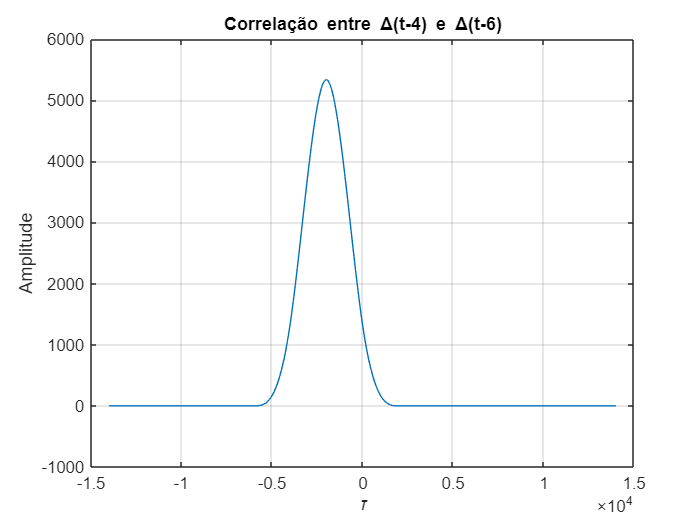

%%% Correlação cruzada entre delta(t-4) e delta(t-6)
T0=4;
tempo = -4:1e-3:10;
[r, largs] = xcorr(2*tripuls(tempo-4,T0), 2*tripuls(tempo-6, T0));
plot(largs, r)
xlabel('\tau'), ylabel('Amplitude'), title('Correlação entre \Delta(t-4) e \Delta(t-6)');
grid;

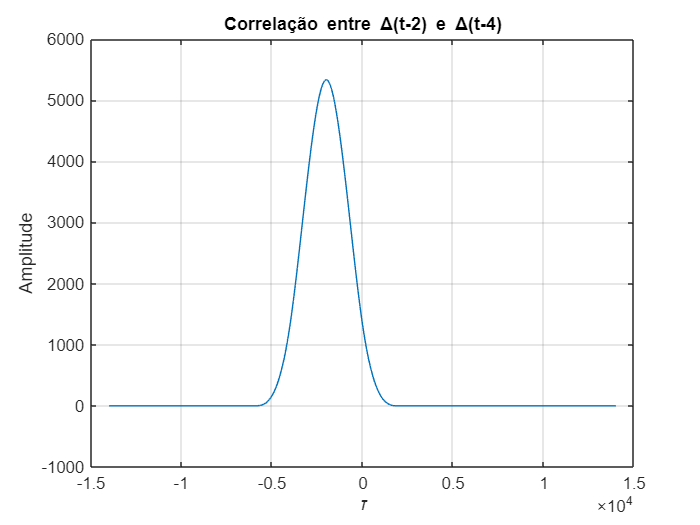

%%% Correlação cruzada entre delta(t-2) e delta(t-4)
T0=4;
tempo = -4:1e-3:10;
[r, largs] = xcorr(2*tripuls(tempo-2,T0), 2*tripuls(tempo-4, T0));
plot(largs, r)
xlabel('\tau'), ylabel('Amplitude'), title('Correlação entre \Delta(t-2) e \Delta(t-4)');
grid; 

## Banda ocupada por sinal

## Exercício 1

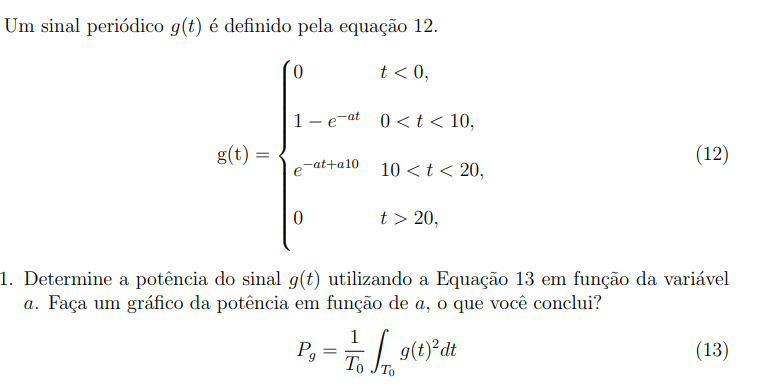

syms t a

%%% Trechos de g(t)
g1 = 1 - exp(-a*t);              % 0 < t < 10
g2 = exp(-a*t + 10*a);           % 10 < t < 20

%%% g(t)² para cada trecho
g1_quad = g1^2;
g2_quad = g2^2;

%%% Cálculo simbólico das integrais
int1 = int(g1_quad, t, 0, 10);
int2 = int(g2_quad, t, 10, 20);

%%% Potência média
T0 = 20;
Pg = (1/T0) * (int1 + int2);

%%% Exibir expressão simbólica
disp('Potência Pg(a) = ');

Potência Pg(a) = 


pretty(simplify(Pg))        %%% exibição da expressão simbólica de maneira mais "natural"

10 a + exp(-10 a) 2 - exp(-20 a) - 1
------------------------------------
                20 a



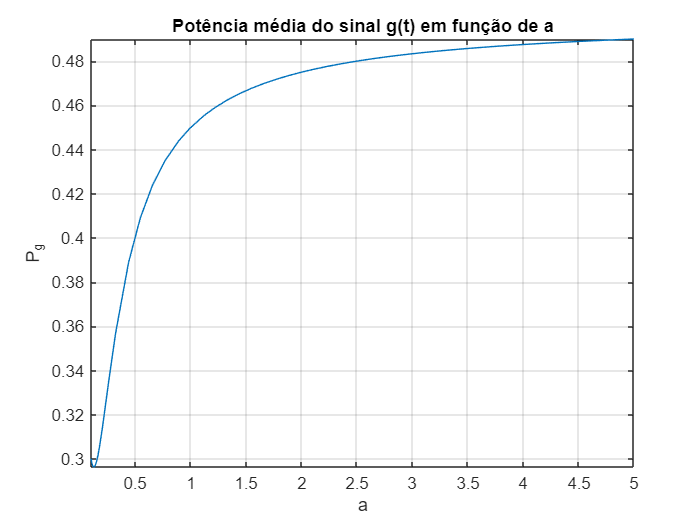

%%% Plotando gráfico da potência em função de a
fplot(Pg, [0.1, 5]); %%% vetor ==> limites do eixo
xlabel('a'), ylabel('P_g'), title('Potência média do sinal g(t) em função de a'), grid;

## Exercício 2

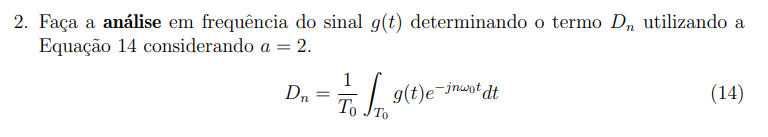

%%% Criando um ambiente simbólico
syms n
w0 = 2*pi/T0;

%%% Determinando a expressão geral paa Dn
Dn = (1/T0) * (int((1 - exp(-2*t))*exp(-1j*n*w0*t), t, 0, 10) + int((exp(-2*t + 2*10))*exp(-1j*n*w0*t), t, 10, 20))

$$Dn = \frac{{\mathrm{e}}^{-20}\,{\mathrm{e}}^{-\pi \,n\,\mathrm{i}}-1}{2\,\left(20+\pi \,n\,\mathrm{i}\right)}+\frac{\left({\mathrm{e}}^{-\pi \,n\,\mathrm{i}}-1\right)\,\mathrm{i}}{2\,n\,\pi }-\frac{{\mathrm{e}}^{-20}\,{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}\,\left({\mathrm{e}}^{20}\,{\mathrm{e}}^{\pi \,n\,\mathrm{i}}\,\mathrm{i}-\mathrm{i}\right)}{2\,\left(\pi \,n-20\,\mathrm{i}\right)}$$

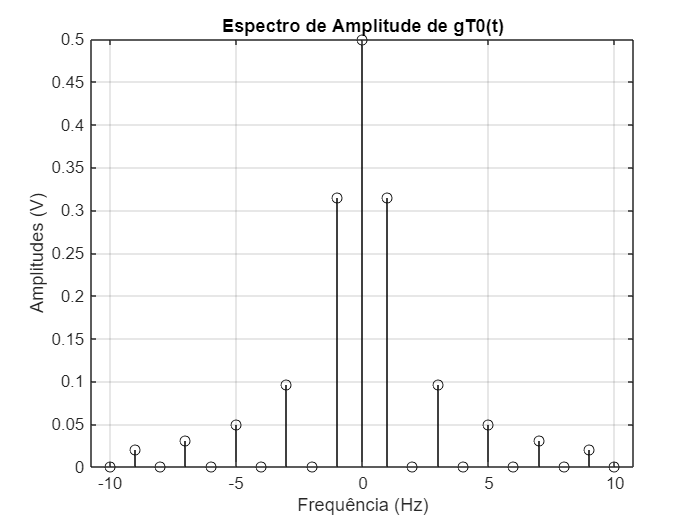

%%% Número de harmônicas para o espectro de amplitude
N = 10;     
n = -N:1:N;
%%% I = 1i;         %correção de um erro do matlab

amplitudes = abs(eval(Dn));

%%% Tratando a indeterminação 0/0 (NaN) no valor médio
amplitudes(N+1) = (1/T0) * (int(1-exp(-2*t), t, 0, 10) + int(exp(-2*t + 10*2), t, 10, 20));
frequencias = linspace(-N,N,2*N+1); 

%%% Plotando o espectro de amplitudes
figure;
stem(frequencias,amplitudes,'Color','k')
title('Espectro de Amplitude de gT0(t)');
xlabel('Frequência (Hz)'), ylabel('Amplitudes (V)'), grid;

## Exercício 3

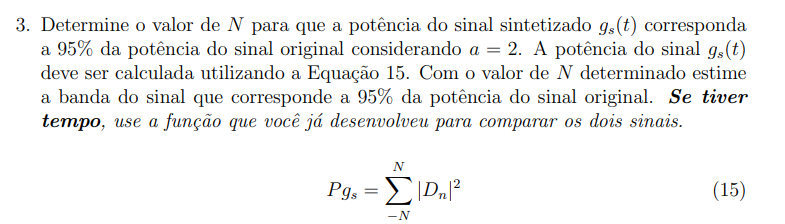

Pg_subs =subs(Pg, a, 2);         %%% substitui a por 2
disp(Pg_subs);                   %%% exibe o resultado

$$\frac{{\mathrm{e}}^{-20}}{20}-\frac{{\mathrm{e}}^{-40}}{40}+\frac{19}{40}$$

Pgs = 0.95*Pg_subs;
Nmax = floor(length(amplitudes)/2);   %%% floor() => aproximar o argumento para um valor inteiro não maior que o argumento
N_determ = 0;                         %%% banda do sinal que contém 95%da potência original

for N = 0 : Nmax
    %%% Índices dos coeficientes entre -N e N
    index = floor((length(amplitudes)/2 - N + 1):(length(amplitudes)/2 + N + 1));
    Pgs = sum(abs(amplitudes(index)).^2);
    
    if Pgs == Pg_subs
        N_determ = N;
        break;
    end
end

fprintf('O menor N que garante 95%% da potência é: %d\n', N_determ);

O menor N que garante 95% da potência é: 0


## Derivando e integrando sinais

## Exercício 1

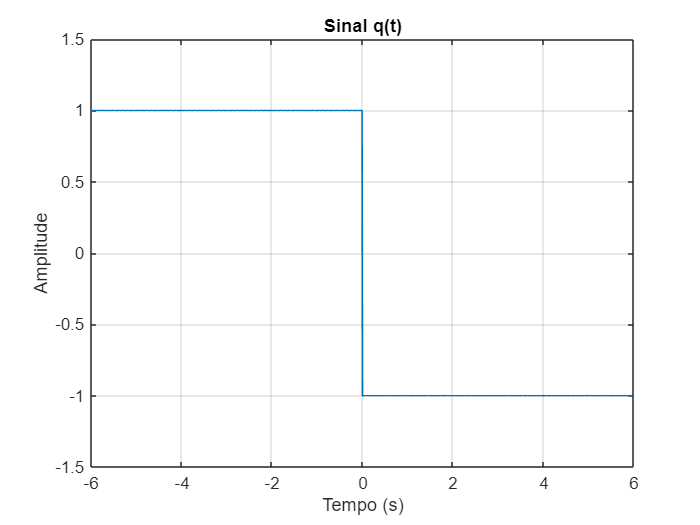

%%% Parâmetros
T0 = 2;                 %%% Período
t = -6:0.01:6;          %%% Tempo
q = zeros(size(t));     %%% Inicializar vetor do sinal q(t)

%%% Construir q(t) com base na derivada do sinal original
for i = 1:length(t)
    t_mod = mod(t(i), T0);              %%% resto da divisão de t(i) por T0
    if t(i) < 0
        t_mod = mod(t(i), T0) - T0;     %%% Garante que t_mod esteja entre [-2, 0[
    end

    %%% Derivada do sinal 
    if t_mod >= -2 && t_mod < 0
        q(i) = 1;
    elseif t_mod >= 0 && t_mod < 2
        q(i) = -1;
    end
end

%%% Plotando o gráfico de g(t)
plot(t, q, 'LineWidth', 1);
xlabel('Tempo (s)'), ylabel('Amplitude'), title('Sinal q(t)');
ylim([-1.5 1.5]), grid;

## Exercício 2

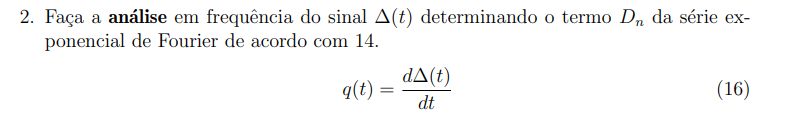

syms n1 t           %%% Ambiente simbólico
T0 = 4;             %%% período
w0 = 2*pi/T0;       %%% freuência angular

%%% Coeficientes Dn
Dn_delta = (1/T0) * (int((t+2)*exp(-1j*n1*w0*t),t,-2,0) + int((-t+2)*exp(-1j*n1*w0*t),t,0,2))

$$Dn\_delta = \frac{1}{{n_{1}}^{2}\,\pi^{2}}-\frac{\mathrm{i}}{n_{1}\,\pi }+\frac{1-{\mathrm{e}}^{\pi \,n_{1}\,\mathrm{i}}+\pi \,n_{1}\,\mathrm{i}}{{n_{1}}^{2}\,\pi^{2}}-\frac{{\mathrm{e}}^{-\pi \,n_{1}\,\mathrm{i}}}{{n_{1}}^{2}\,\pi^{2}}$$

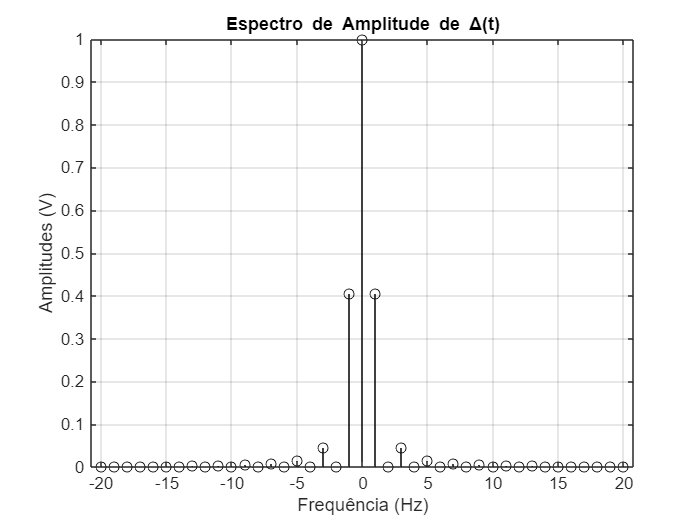

%%% Número de harmônicas para o espectro de amplitude
N1 = 20;     
n1 = -N1:1:N1;

amplitudes_delta = abs(eval(Dn_delta));

%%% Tratando a indeterminação 0/0 (NaN) no valor médio
amplitudes_delta(N1+1) = (1/T0) * (int(t+2, t, -2, 0) + int(-t+2, t, 0, 2));
frequencias_delta = linspace(-N1,N1,2*N1+1); 

%%% Plotando o espectro de amplitudes
figure;
stem(frequencias_delta,amplitudes_delta,'Color','k')
title('Espectro de Amplitude de \Delta(t)');
xlabel('Frequência (Hz)'), ylabel('Amplitudes (V)'), grid;

## Exercício 3

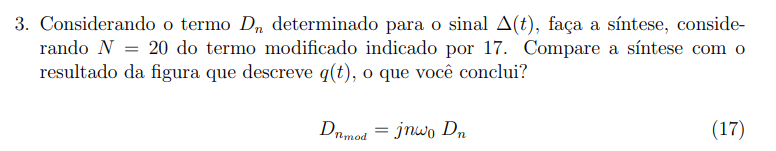

%%%Criando um ambiente simbólico
syms n2 n3 n4 t

Dn_delta = (1/T0) * (int((t+2)*exp(-1j*n2*w0*t),t,-2,0) + int((-t+2)*exp(-1j*n2*w0*t),t,0,2))

$$Dn\_delta = \frac{1}{{n_{2}}^{2}\,\pi^{2}}-\frac{\mathrm{i}}{n_{2}\,\pi }+\frac{1-{\mathrm{e}}^{\pi \,n_{2}\,\mathrm{i}}+\pi \,n_{2}\,\mathrm{i}}{{n_{2}}^{2}\,\pi^{2}}-\frac{{\mathrm{e}}^{-\pi \,n_{2}\,\mathrm{i}}}{{n_{2}}^{2}\,\pi^{2}}$$

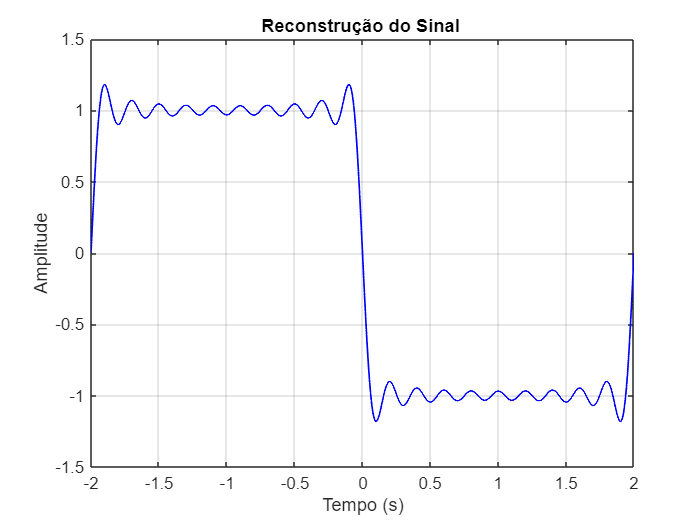

Dn_mod = 1j*n2*w0*Dn_delta;

%%% Reconstrução do sinal utilizando a síntese
N2=20;
n2 = -N2:1:N2;
Dn_mod2 = eval(Dn_mod);
Dn_mod2(N2+1) = 0;                       % valor médio de q(t)
aux = 0;

tempo1 = -2:1e-3:2;

%%% síntese de q(t)
for k = 1:length(n2)
    aux  =  aux + Dn_mod2(k)*exp(1j * n2(k) * w0 .* tempo1);
end

%%% Plotando os sinais sintetizado e original
figure;
plot(tempo1,real(aux),'LineWidth',1,"Color",'b')
title('Reconstrução do Sinal ');
xlabel('Tempo (s)'),ylabel('Amplitude'), grid;

É possível concluir que o "shape" do sinal sintetizado acima se aproxima do sinal $q\left(t\right)$determinado. À medida que aumentamos

o número de harmônicas, a síntese torna-se cada vez mais próxima de uma onda quadrada. Ao multiplicarmos os coeficientes 

Dn do sinal $\Delta \left(t\right)$, estamos aplicando a derivada no domínio de Fourier. Assim, em posse dos coeficientes Dn do sinal original,

a derivada do sinal é obtida facilmente e, por conseguinte, os coeficientes Dn de q(t).

## Exercício 4

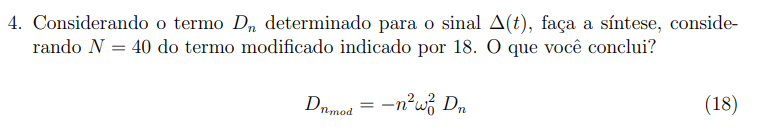

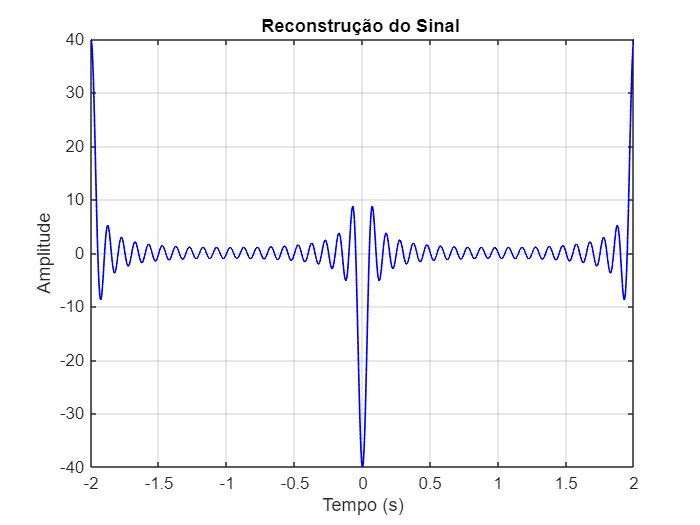

Dn_delta = (1/T0) * (int((t+2)*exp(-1j*n3*w0*t),t,-2,0) + int((-t+2)*exp(-1j*n3*w0*t),t,0,2));
Dn_mod3 = -n3.^2*w0^2*Dn_delta;

%%% Definição dos novos parâmetros 
N3 = 40;
n3 = -N3:1:N3;
Dn_mod4 = eval(Dn_mod3);
Dn_mod4(N3+1) = 0;             %%% valor médio de dq/dt

aux2 = 0;
tempo2 = -2:1e-3:2;

%%% síntese de q(t)
for k = 1:length(n3)
    aux2  =  aux2 + Dn_mod4(k)*exp(1j * n3(k) * w0 .* tempo2); 
end

%%% Plotando os sinais sintetizado e original
figure;
plot(tempo2,real(aux2),'LineWidth',1,"Color",'b')
title('Reconstrução do Sinal ');
xlabel('Tempo (s)'),ylabel('Amplitude'), grid;

Ao multiplicarmos por $-\textrm{n²}\omega_{0\;} ²$, estamos deivando o sinal $q\left(t\right)$ (segunda derivada do sinal $\Delta \left(t\right)$. Portanto, a síntese deve

se aproximar de zero á medida que aumentamos a quantidade de harmônicas. Fato este que ocorre se modifcarmos N3

no código acima 

## Exercício 5

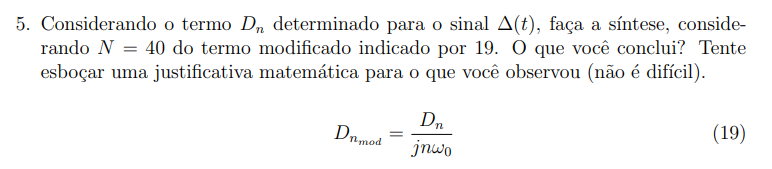

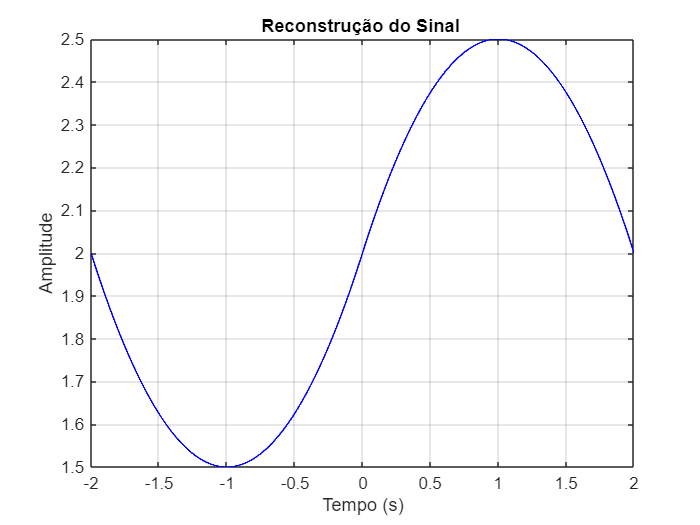

Dn_delta = (1/T0) * (int((t+2)*exp(-1j*n4*w0*t),t,-2,0) + int((-t+2)*exp(-1j*n4*w0*t),t,0,2));
Dn_mod5 = Dn_delta ./ (1j*n4*w0);
N4 = 40;
n4 = -N4:1:N4;
Dn_mod6 = eval(Dn_mod5);

%%% Ao integrarmos uma função no domínio de Fourier, basta dividirmos por jnw
%%% Assim, a Equação 19 realiza esse cálculo.
%%% O valor médio da integral de delta(t) vale: 
Dn_mod6(N4+1) =  (1/T0) * (int(int(t+2,t,-2,0), t, -2, 0) + int(int(-t+2, t, 0, 2), t, 0, 2));  

aux3 = 0;
tempo2 = -2:1e-3:2;

%%% síntese de q(t)
for k = 1:length(n4)
    aux3  =  aux3 + Dn_mod6(k)*exp(1j * n4(k) * w0 .* tempo2); 
end

%%% Plotando os sinais sintetizado e original
figure;
plot(tempo2,real(aux3),'LineWidth',1,"Color",'b')
title('Reconstrução do Sinal ');
xlabel('Tempo (s)'),ylabel('Amplitude'), grid;

Analisando o sinal original $\Delta \left(t\right)$, temos que ele é definido por partes da seguinte forma:

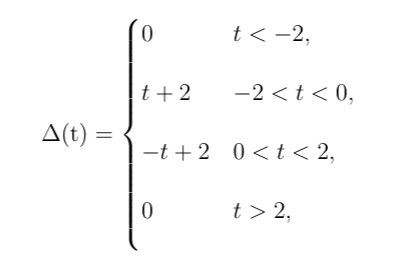

No código acima, estamos integrando tal sinal por meio da propriedade de integração no domínio de Fourier.

Realizando a integração para os trechos $-2<t<0\;\;e\;\;0<t<2$ temos:

$\int_{-2}^0 \left(t+2\right)\textrm{dt}=\frac{\textrm{t²}}{2}+2t+C_1$ e $\int_0^2 \left(-t+2\right)\textrm{dt}=-\frac{\textrm{t²}}{2}-2t+C_2$. 

Portanto, como podemos observar no gráfico, a função possui comportamento quadrático. No primeiro intervalo,

a concavidade da parábola está voltada para cima, o que condiz com o resultado encontrado na primeira integral.

Analogamente, concluímos que o resultado da segunda integral também está de acordo com o esperado.